# Diamonds dataset

Clear workspace

clear all; clc; close all;

## Initialize variables

Load table

diamonds = readtable('diamonds.csv')

diamonds = 53940×11 table
    Var1    carat         cut         color    clarity     depth    table    price     x       y       z  
    ____    _____    _____________    _____    ________    _____    _____    _____    ____    ____    ____

      1     0.23     {'Ideal'    }    {'E'}    {'SI2' }    61.5      55       326     3.95    3.98    2.43
      2     0.21     {'Premium'  }    {'E'}    {'SI1' }    59.8      61       326     3.89    3.84    2.31
      3     0.23     {'Good'     }    {'E'}    {'VS1' }    56.9      65       327     4.05    4.07    2.31
      4     0.29     {'Premium'  }    {'I'}    {'VS2' }    62.4 

Transform categorical variables

diamonds.cut = categorical(diamonds.cut);
diamonds.color = categorical(diamonds.color);
diamonds.clarity = categorical(diamonds.clarity);

## Some Histograms for better understanding of the data

nbins = 50

nbins = 50

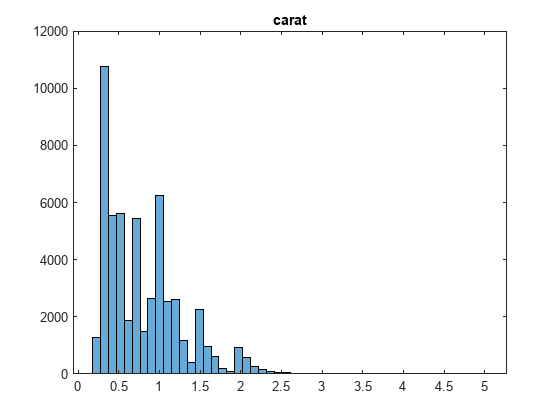

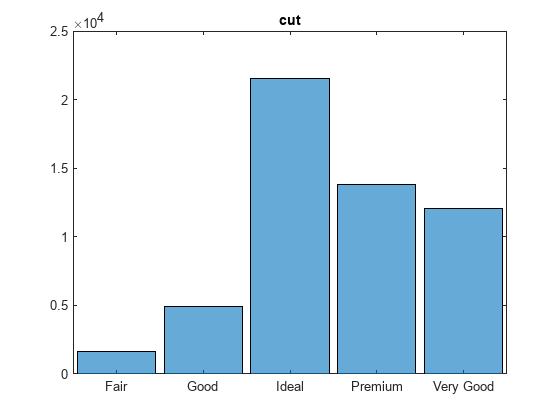

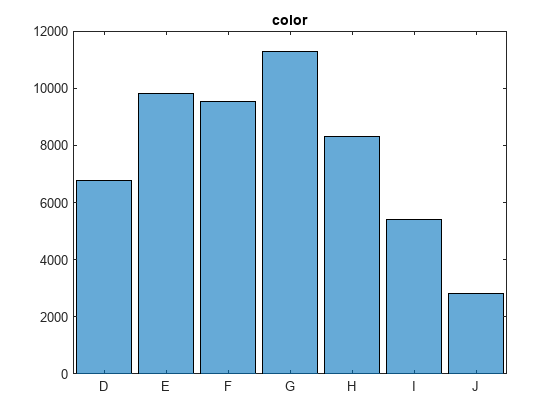

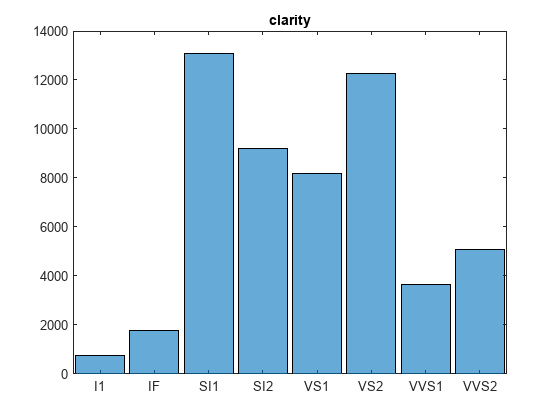

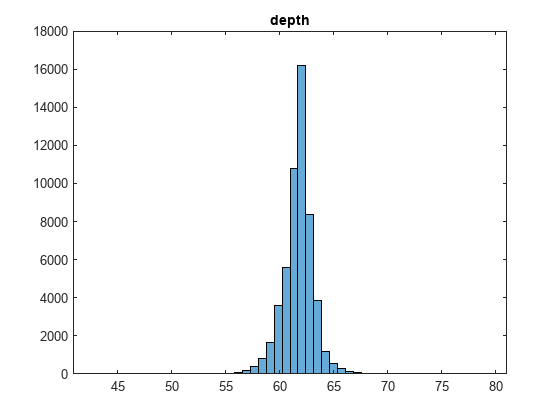

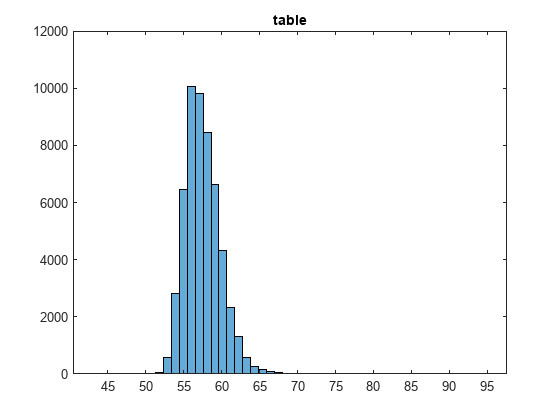

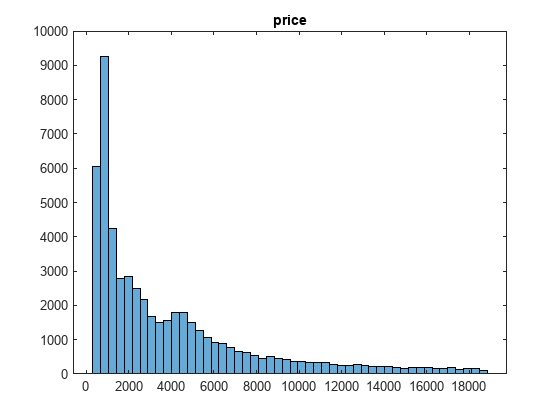

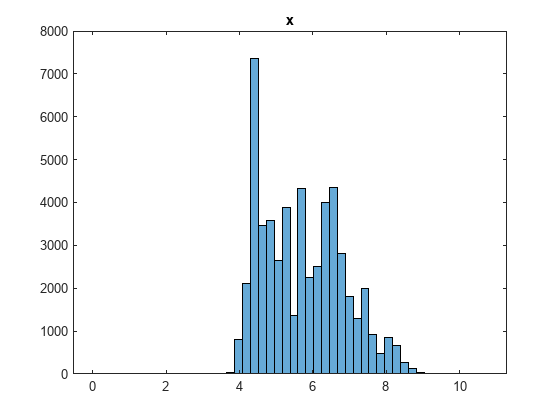


for col = 2: width(diamonds)
    figure
    if iscategorical(table2array(diamonds(:,col)))
        histogram(table2array(diamonds(:,col)))
    else
        histogram(table2array(diamonds(:,col)), nbins)
    end
    title(diamonds.Properties.VariableNames{col})
%     saveas(gcf,strcat('02_Diamonds/Hist_', diamonds.Properties.VariableNames{col}, '.png') )
end

## Prices for different categories

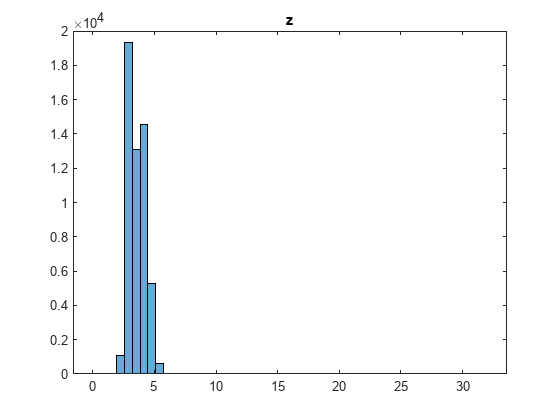

hist_edges = linspace(0, max(diamonds.price), nbins+1);
plot_edges = linspace(hist_edges(2)/2, (hist_edges(end-1)+hist_edges(end))/2, nbins);

colors = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#A2142F", "#0072BD"];
colororder(colors)

### Cut

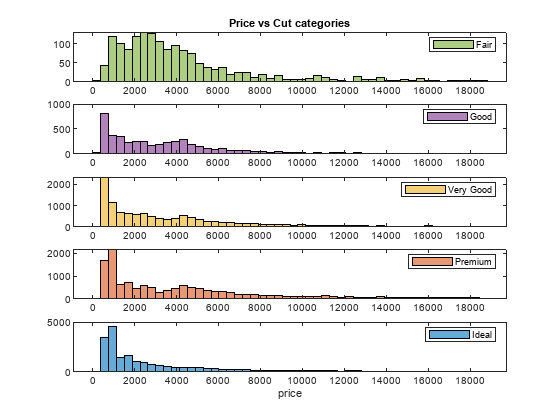

cut_categories = unique(diamonds.cut);
cut_categories = {'Ideal';'Premium';'Very Good';'Good';'Fair'};

figure
for ii = 1:size(cut_categories)
    X(ii,:) = histcounts( diamonds.price(diamonds.cut == cut_categories(ii)), hist_edges);
    subplot(size(cut_categories,1), 1, size(cut_categories,1)+1-ii)
    histogram( diamonds.price(diamonds.cut == cut_categories(ii)), hist_edges, FaceColor=colors(ii));
    legend(cut_categories(ii))
    if ii ==1
        xlabel('price')
    end
end
title('Price vs Cut categories')

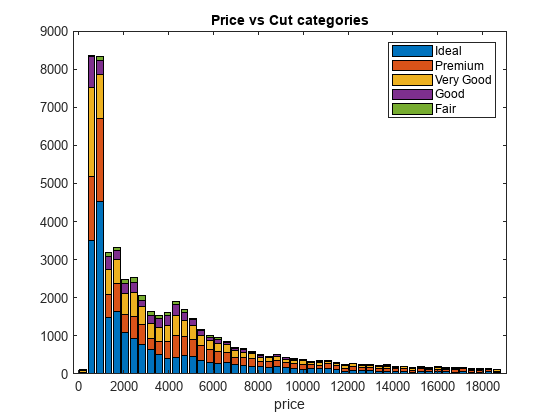

% saveas(gcf,strcat('02_Diamonds/Hist_PriceCut.png') )

figure
bar(plot_edges, X, 'stacked')
xlabel('price')
legend(cut_categories)
title('Price vs Cut categories')

% saveas(gcf,strcat('02_Diamonds/Hist_PriceCut_stacked.png') )

### Color

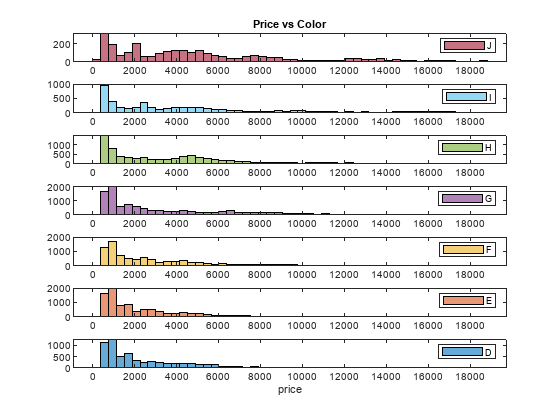

color_categories = unique(diamonds.color);

figure
for ii = 1:size(color_categories)
    X(ii,:) = histcounts( diamonds.price(diamonds.color == color_categories(ii)), hist_edges);
    subplot(size(color_categories,1), 1, size(color_categories,1)+1-ii)
    histogram( diamonds.price(diamonds.color == color_categories(ii)), hist_edges, FaceColor=colors(ii));
    legend(color_categories(ii))
    if ii ==1
        xlabel('price')
    end
end
title('Price vs Color')

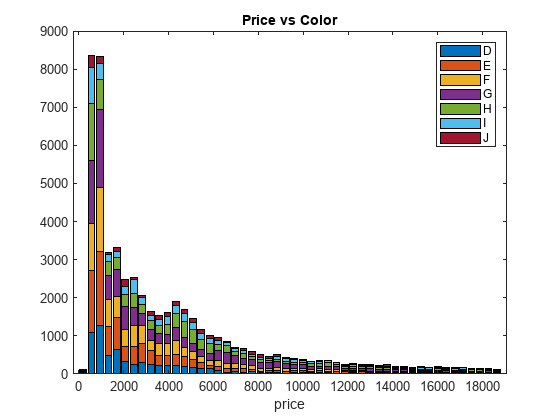

% saveas(gcf,strcat('02_Diamonds/Hist_PriceColor.png') )

figure
bar(plot_edges, X, 'stacked')
xlabel('price')
legend(color_categories)
title('Price vs Color')

% saveas(gcf,strcat('02_Diamonds/Hist_PriceColor_stacked.png') )

### Clarity

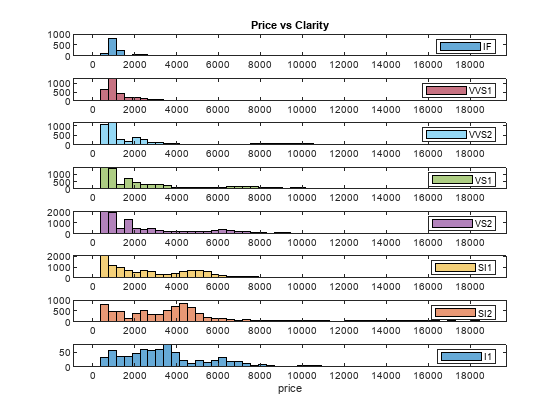

clarity_categories = unique(diamonds.clarity);
clarity_categories = {'I1'; 'SI2'; 'SI1'; 'VS2'; 'VS1'; 'VVS2'; 'VVS1'; 'IF'};

figure
for ii = 1:size(clarity_categories)
    X(ii,:) = histcounts( diamonds.price(diamonds.clarity == clarity_categories(ii)), hist_edges);
    subplot(size(clarity_categories,1), 1, size(clarity_categories,1)+1-ii)
    histogram( diamonds.price(diamonds.clarity == clarity_categories(ii)), hist_edges, FaceColor=colors(ii));
    legend(clarity_categories(ii))
    if ii ==1
        xlabel('price')
    end
end
title('Price vs Clarity')

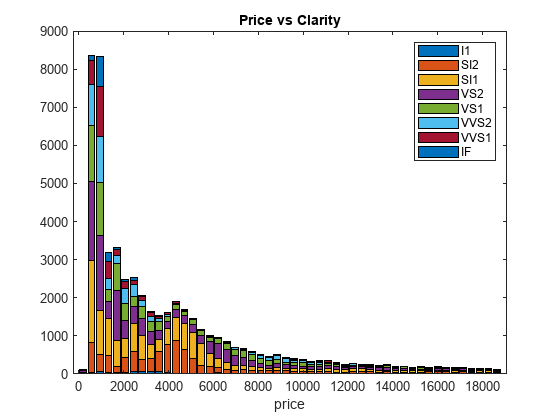

% saveas(gcf,strcat('02_Diamonds/Hist_PriceClarity.png') )

figure
bar(plot_edges, X, 'stacked')
xlabel('price')
legend(clarity_categories)
title('Price vs Clarity')

% saveas(gcf,strcat('02_Diamonds/Hist_PriceClarity_stacked.png') )

## Gplot of non-categorical variables (vs price)

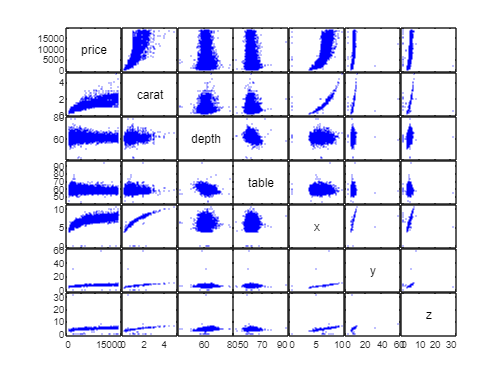

X = [diamonds.price diamonds.carat diamonds.depth diamonds.table diamonds.x diamonds.y diamonds.z];

xnames = {'price', 'carat', 'depth', 'table', 'x', 'y', 'z'};

figure
[h, ax] = gplotmatrix( X,[],[],[],[],[],[],'variable',xnames);

% saveas(gcf,strcat('02_Diamonds/All_vars.png') )

Compute correlation

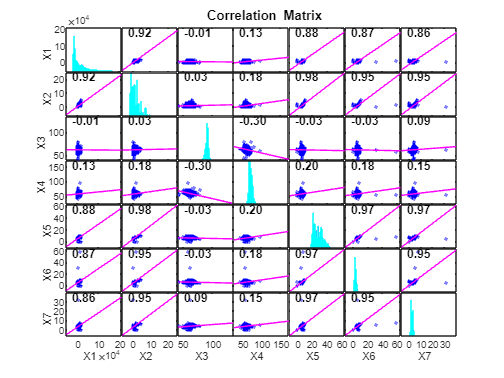

R = 7×7 table
            X1          X2           X3          X4           X5           X6          X7     
          _________    ________    _________    ________    _________    _________    ________

    X1            1     0.92159    -0.010647     0.12713      0.88444      0.86542     0.86125
    X2      0.92159           1     0.028224     0.18162      0.97509      0.95172     0.95339
    X3    -0.010647    0.028224            1    -0.29578    -0.025289    -0.029341    0.094924
    X4      0.12713     0.18162     -0.29578           1      0.19534      0.18376     0.15093
    X5      0.88444     0.97509    -0.025289     0.19534            1       0.9747     0.970

PValue = 7×7 table
             X1            X2             X3             X4            X5            X6             X7      
          ___________    __________    ___________    ___________    __________    __________    ___________

    X1              1             0       0.013403    3.7615e-193             0             0              0
    X2              0             1     5.5179e-11              0             0             0              0
    X3       0.013403    5.5179e-11              1              0    4.2482e-09    9.3821e-12    3.4955e-108
    X4    3.7615e-193             0              0              1             0             0    2.9297e-272
    X5

[R,PValue] = corrplot(array2table(X))

% saveas(gcf,strcat('02_Diamonds/All_vars_corr.png') )

Depth and table don´t present a high influence on price, so these variables will be neglected from the model.

## Focused at dimensions

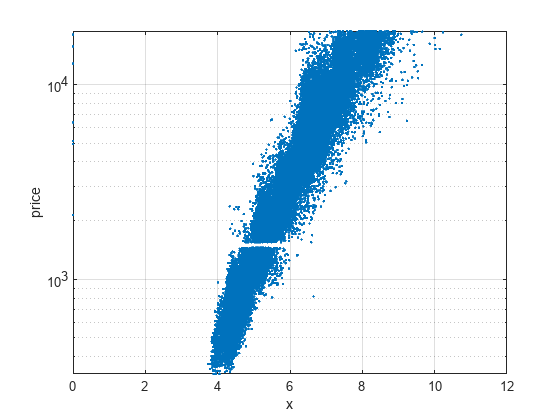

figure
semilogy(diamonds.x, diamonds.price, '.')
xlabel('x')
ylabel('price')
grid on

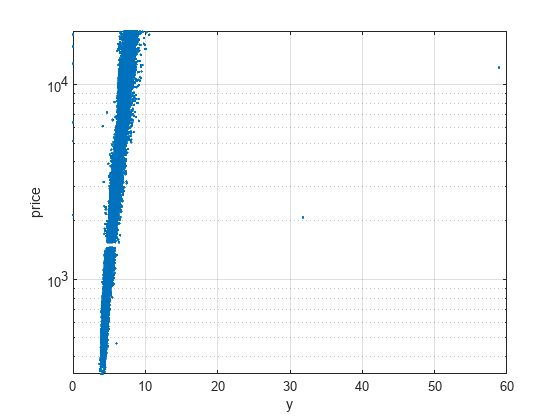

% saveas(gcf,strcat('02_Diamonds/x_unfilter.png') )

figure
semilogy(diamonds.y, diamonds.price, '.')
xlabel('y')
ylabel('price')
grid on

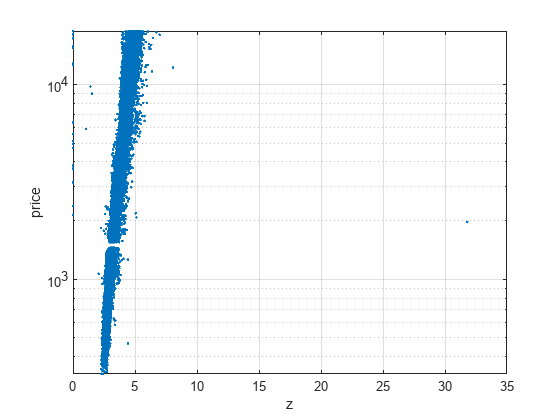

% saveas(gcf,strcat('02_Diamonds/y_unfilter.png') )

figure
semilogy(diamonds.z, diamonds.price, '.')
xlabel('z')
ylabel('price')
grid on

% saveas(gcf,strcat('02_Diamonds/z_unfilter.png') )

### Apply filters

Remove zeroes from the table

idx = (diamonds.x > 0 & diamonds.y > 0 & diamonds.z > 0);
diamonds_filtered = diamonds(idx,:);

Remove clearly outliers from the data (y > 30 or z> 30)

idx = (diamonds_filtered.y < 30 & diamonds_filtered.z < 30);
diamonds_filtered = diamonds_filtered(idx,:);

### Plot filtered data

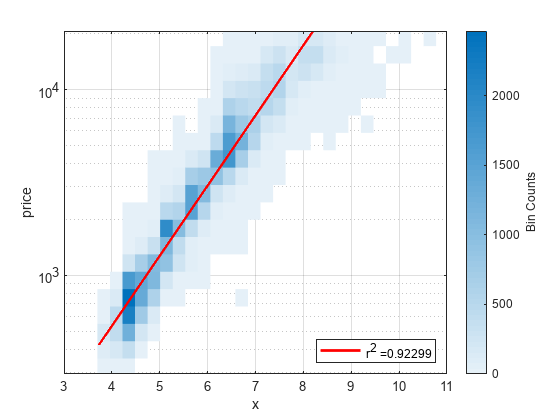

figure
% semilogy(diamonds_filtered.x, diamonds_filtered.price, '.')
binscatter(diamonds_filtered.x, diamonds_filtered.price)
set(gca,'YScale', 'log')
[f, gof] = fit(diamonds_filtered.x, log(diamonds_filtered.price), 'poly1');
x1 = linspace(min(diamonds_filtered.x), max(diamonds_filtered.x), 1001);
hold on
semilogy(x1, exp(f.p1*x1 + f.p2), 'r', LineWidth=2)
hold off
xlabel('x')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')

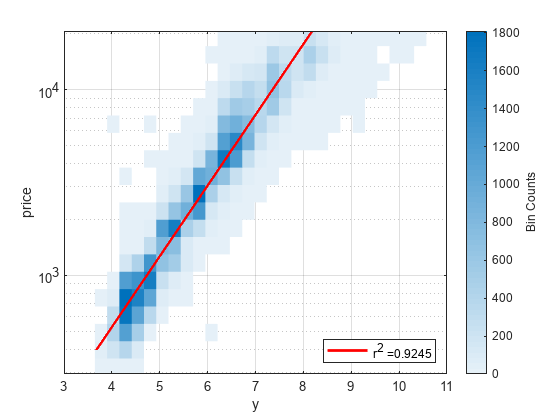

% saveas(gcf,strcat('02_Diamonds/x_filter.png') )

figure
% semilogy(diamonds_filtered.y, diamonds_filtered.price, '.')
binscatter(diamonds_filtered.y, diamonds_filtered.price)
set(gca,'YScale', 'log')
[f, gof] = fit(diamonds_filtered.y, log(diamonds_filtered.price), 'poly1');
x1 = linspace(min(diamonds_filtered.y), max(diamonds_filtered.y), 1001);
hold on
semilogy(x1, exp(f.p1*x1 + f.p2), 'r', LineWidth=2)
hold off
xlabel('y')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')

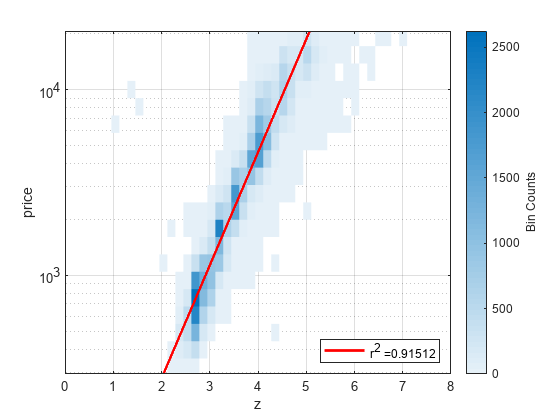

% saveas(gcf,strcat('02_Diamonds/y_filter.png') )

figure
% semilogy(diamonds_filtered.z, diamonds_filtered.price, '.')
binscatter(diamonds_filtered.z, diamonds_filtered.price)
set(gca,'YScale', 'log')
[f, gof] = fit(diamonds_filtered.z, log(diamonds_filtered.price), 'poly1');
x1 = linspace(min(diamonds_filtered.z), max(diamonds_filtered.z), 1001);
hold on
semilogy(x1, exp(f.p1*x1 + f.p2), 'r', LineWidth=2)
hold off
xlabel('z')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')

% saveas(gcf,strcat('02_Diamonds/z_filter.png') )

### Are the 3 variables independent? And carat?

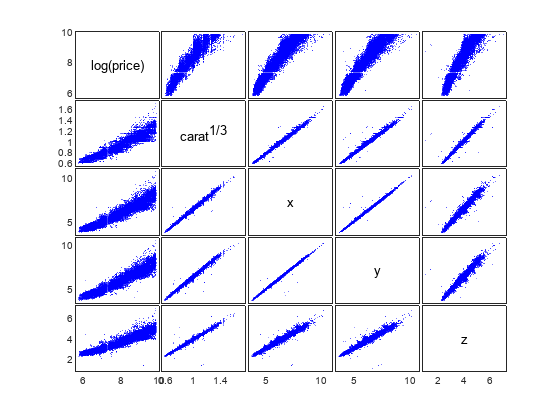

X = [log(diamonds_filtered.price) diamonds_filtered.carat.^(1/3) diamonds_filtered.x diamonds_filtered.y diamonds_filtered.z];

xnames = {'log(price)', 'carat^{1/3}', 'x', 'y', 'z'};

[h, ax] = gplotmatrix( X,[],[],[],[],[],[],'variable',xnames);

% saveas(gcf,strcat('02_Diamonds/Linear_vars.png') )

Compute correlation

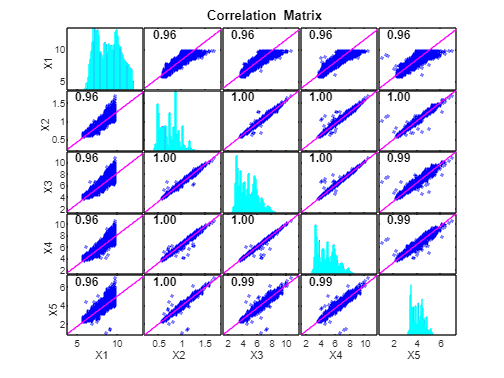

R = 5×5 table
           X1         X2         X3         X4         X5    
          _______    _______    _______    _______    _______

    X1          1    0.96105    0.96072    0.96151    0.95662
    X2    0.96105          1    0.99762    0.99709    0.99643
    X3    0.96072    0.99762          1    0.99866    0.99108
    X4    0.96151    0.99709    0.99866          1    0.99073
    X5    0.95662    0.99643    0.99108    0.99073          1


PValue = 5×5 table
          X1       X2       X3       X4       X5   
          _____    _____    _____    _____    _____

    X1      1        0        0        0        0  
    X2      0        1        0        0        0  
    X3      0        0        1        0        0  
    X4      0        0        0        1        0  
    X5      0        0        0        0        1  


[R,PValue] = corrplot(array2table(X))

% saveas(gcf,strcat('02_Diamonds/Linear_vars_corr.png') )

As diamond shape seems to be standard, x, y & z are linearly related, while carat (which is a measure of their mass) scales with x^3

This means that among all the numerical variables 

## Regression with carat

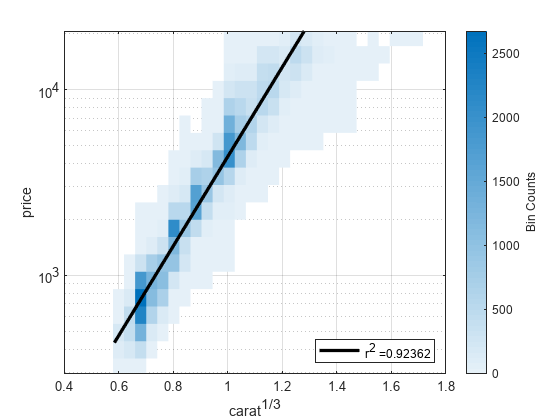

figure
% semilogy(diamonds_filtered.carat, diamonds_filtered.price, '.')
binscatter(diamonds_filtered.carat.^(1/3), diamonds_filtered.price)
set(gca,'YScale', 'log')
[f, gof] = fit(diamonds_filtered.carat.^(1/3), log(diamonds_filtered.price), 'poly1');
x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);
hold on
semilogy(x1, exp(f.p1*x1 + f.p2), 'k', LineWidth=2.5)
hold off
xlabel('carat^{1/3}')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')

% saveas(gcf,strcat('02_Diamonds/carat_regression.png') )

### Include clarity in the equation

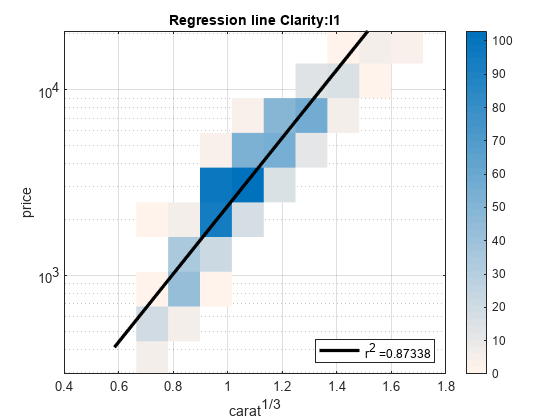

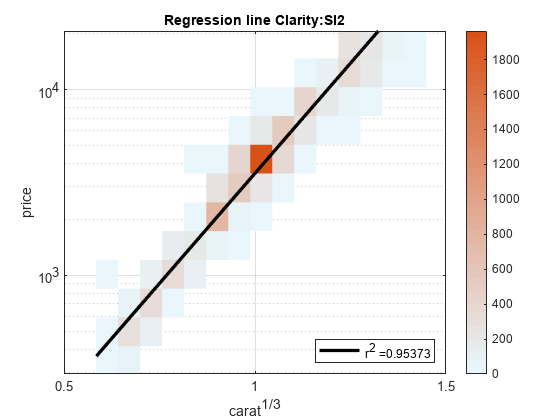

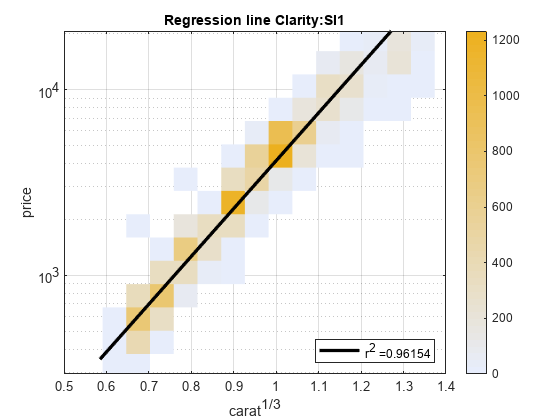

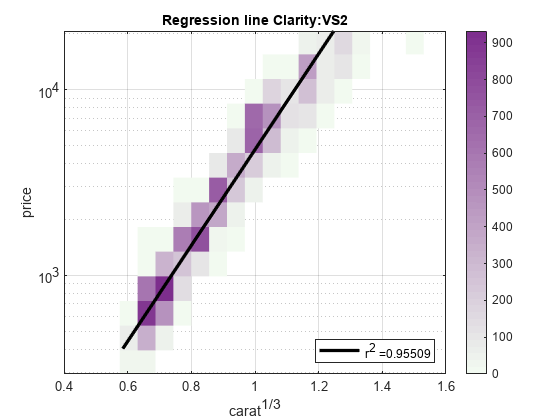

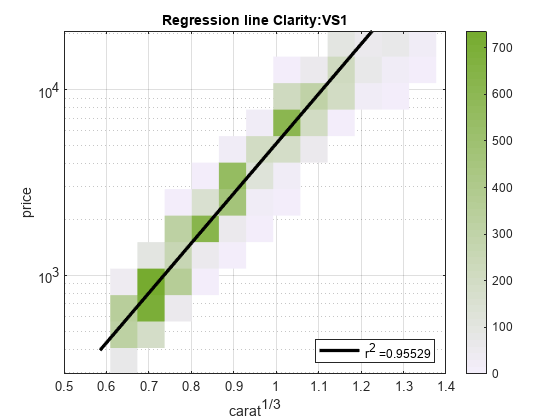

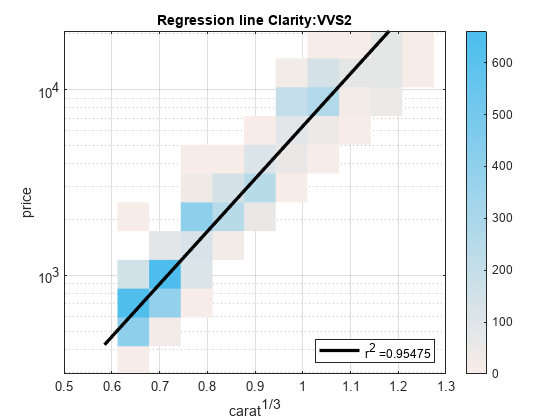

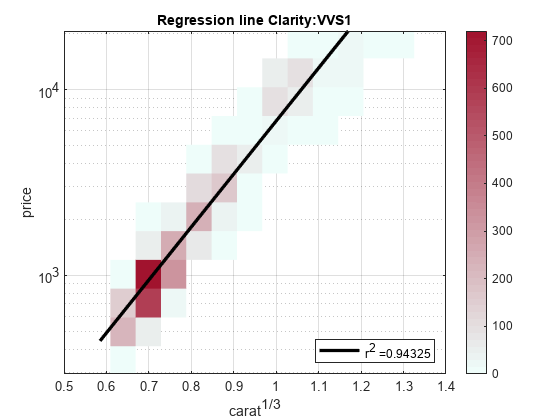

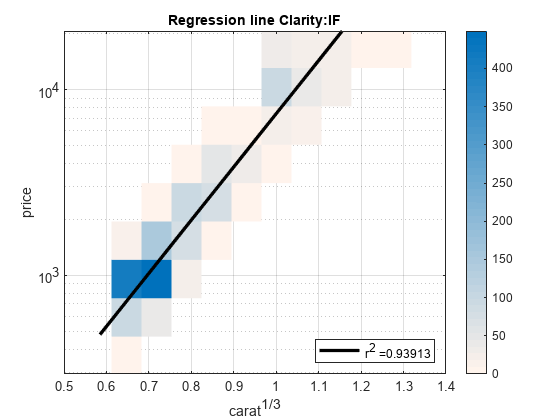

clarity_categories = unique(diamonds_filtered.clarity);
clarity_categories = {'I1'; 'SI2'; 'SI1'; 'VS2'; 'VS1'; 'VVS2'; 'VVS1'; 'IF'};
colors = [[0, 0.4470, 0.7410], 
          [0.8500, 0.3250, 0.0980], 
          [0.9290, 0.6940, 0.1250], 
          [0.4940, 0.1840, 0.5560], 
          [0.4660, 0.6740, 0.1880], 
          [0.3010, 0.7450, 0.9330], 
          [0.6350, 0.0780, 0.1840], 
          [0, 0.4470, 0.7410]];

for ii = 1:size(clarity_categories)
    idx = diamonds_filtered.clarity==clarity_categories(ii);

    figure
    binscatter(diamonds_filtered.carat(idx).^(1/3), diamonds_filtered.price(idx))
    set(gca,'YScale', 'log')
    colormap_graded(colors(ii,:));
    colorbar
    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);
    hold on
    semilogy(x1, exp(f.p1*x1 + f.p2), 'k', LineWidth=2.5)
    hold off
    xlabel('carat^{1/3}')
    ylabel('price')
    grid on
    ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
    legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')
    title(strcat('Regression line Clarity: ',string(clarity_categories(ii))))
%     saveas(gcf,strcat('02_Diamonds/carat_regression_',string(clarity_categories(ii)),'.png') )
end

Now gather all the regression lines

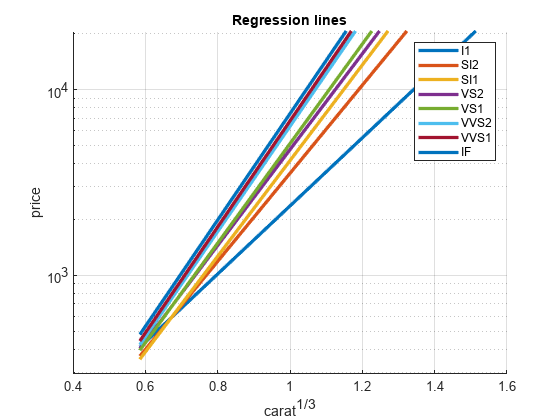

x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);

figure
hold on
for ii = 1:size(clarity_categories)
    idx = diamonds_filtered.clarity==clarity_categories(ii);

    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    semilogy(x1, exp(f.p1*x1 + f.p2), color=colors(ii,:), LineWidth=2.5)
end
hold off
set(gca,'YScale', 'log')
xlabel('carat^{1/3}')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend(clarity_categories)
title(strcat('Regression lines'))

% saveas(gcf,strcat('02_Diamonds/carat_regression_all.png') )

### Test for Color

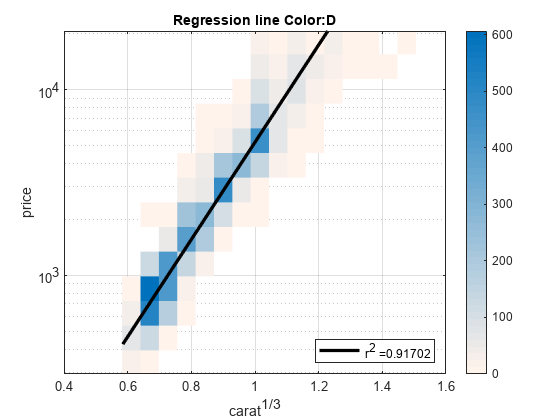

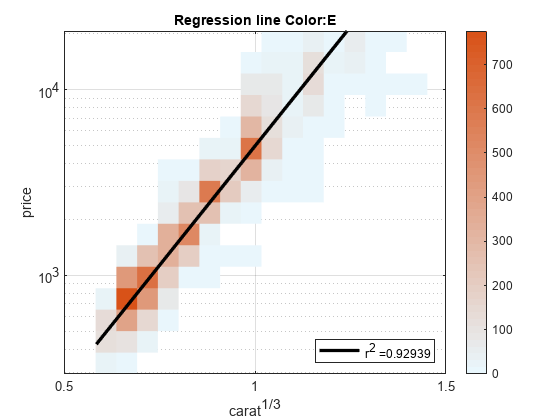

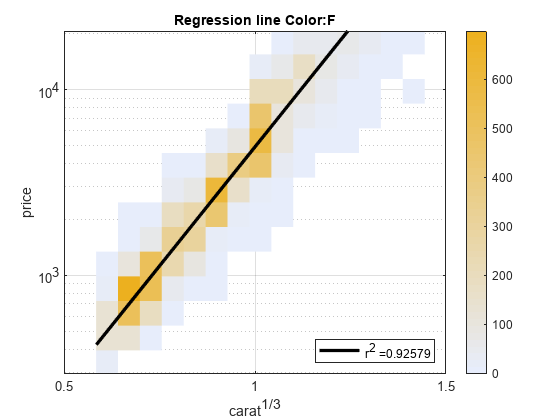

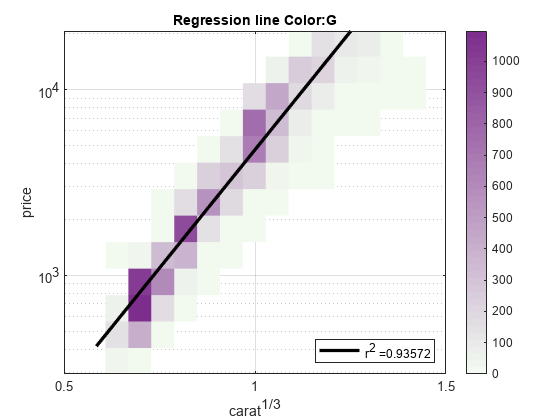

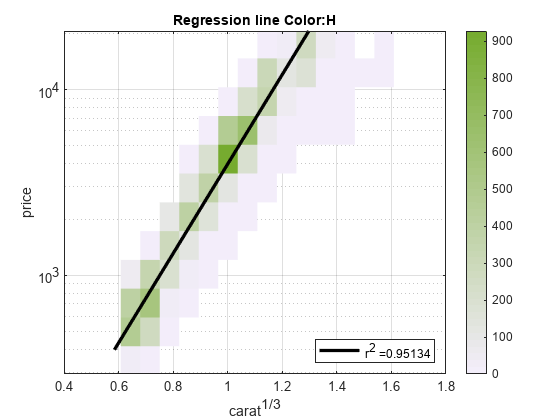

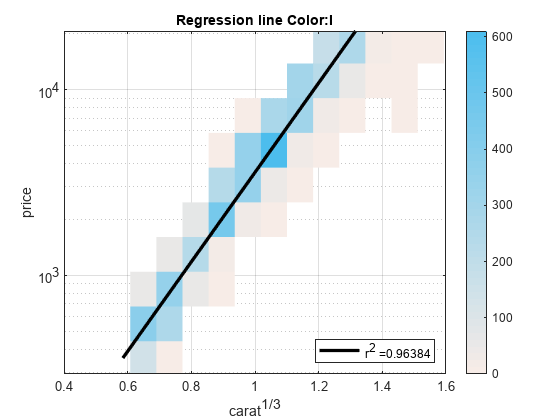

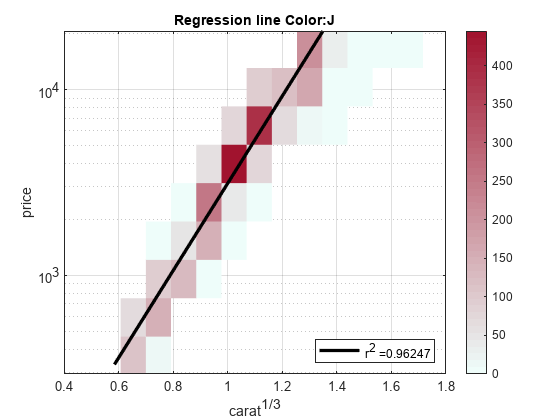

color_categories = unique(diamonds_filtered.color);

for ii = 1:size(color_categories)
    idx = diamonds_filtered.color==color_categories(ii);

    figure
    binscatter(diamonds_filtered.carat(idx).^(1/3), diamonds_filtered.price(idx))
    set(gca,'YScale', 'log')
    colormap_graded(colors(ii,:));
    colorbar
    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);
    hold on
    semilogy(x1, exp(f.p1*x1 + f.p2), 'k', LineWidth=2.5)
    hold off
    xlabel('carat^{1/3}')
    ylabel('price')
    grid on
    ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
    legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')
    title(strcat('Regression line Color: ',string(color_categories(ii))))
%     saveas(gcf,strcat('02_Diamonds/carat_regression_color',string(color_categories(ii)),'.png') )
end

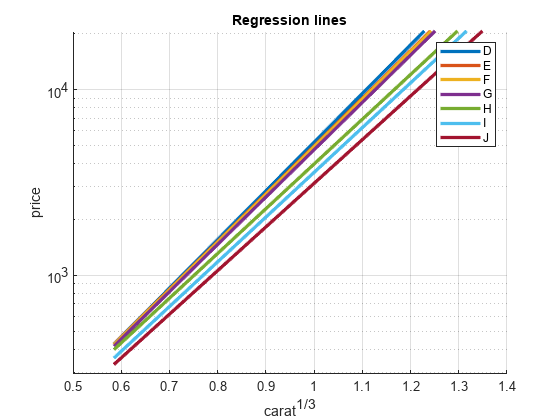

x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);

figure
hold on
for ii = 1:size(color_categories)
    idx = diamonds_filtered.color==color_categories(ii);

    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    semilogy(x1, exp(f.p1*x1 + f.p2), color=colors(ii,:), LineWidth=2.5)
end
hold off
set(gca,'YScale', 'log')
xlabel('carat^{1/3}')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend(color_categories)
title(strcat('Regression lines'))
% saveas(gcf,strcat('02_Diamonds/carat_regression_color_all.png') )

### Test for Cut

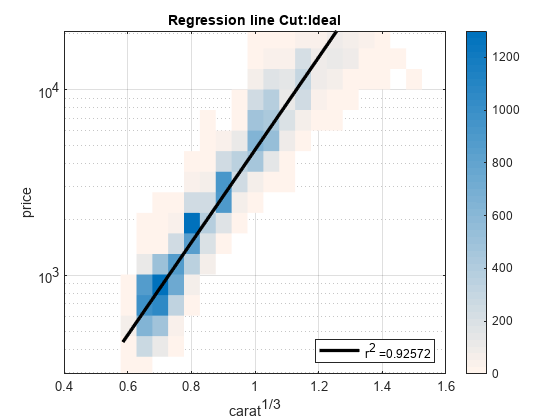

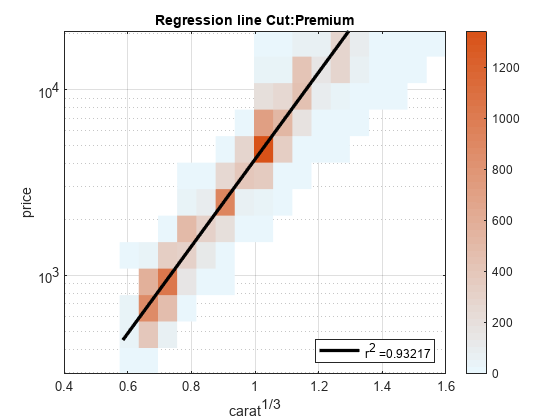

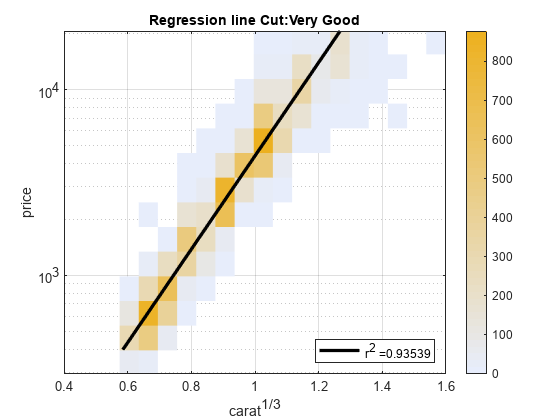

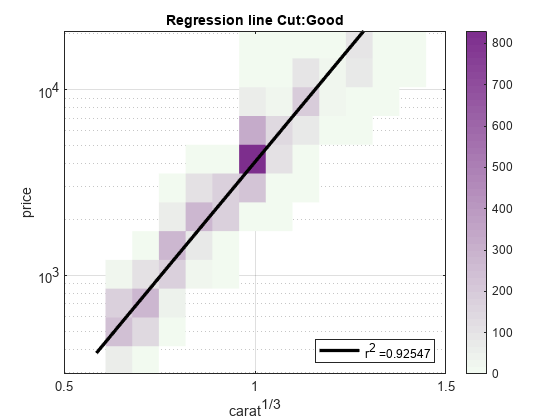

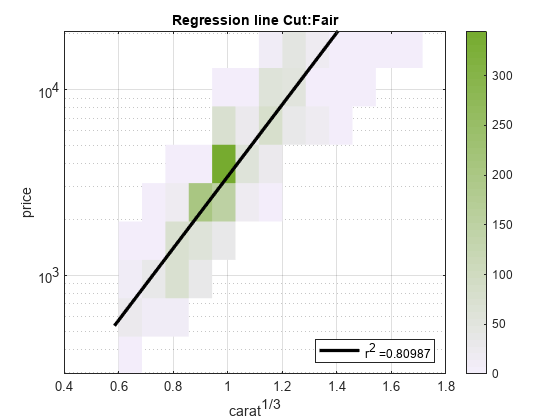

cut_categories = unique(diamonds_filtered.cut);
cut_categories = {'Ideal';'Premium';'Very Good';'Good';'Fair'};

color_categories = unique(diamonds_filtered.color);

for ii = 1:size(cut_categories)
    idx = diamonds_filtered.cut==cut_categories(ii);

    figure
    binscatter(diamonds_filtered.carat(idx).^(1/3), diamonds_filtered.price(idx))
    set(gca,'YScale', 'log')
    colormap_graded(colors(ii,:));
    colorbar
    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);
    hold on
    semilogy(x1, exp(f.p1*x1 + f.p2), 'k', LineWidth=2.5)
    hold off
    xlabel('carat^{1/3}')
    ylabel('price')
    grid on
    ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
    legend('',strcat(' r^2 = ',num2str(gof.rsquare)), 'Location','southeast')
    title(strcat('Regression line Cut: ',string(cut_categories(ii))))
%     saveas(gcf,strcat('02_Diamonds/carat_regression_cut_',string(cut_categories(ii)),'.png') )
end

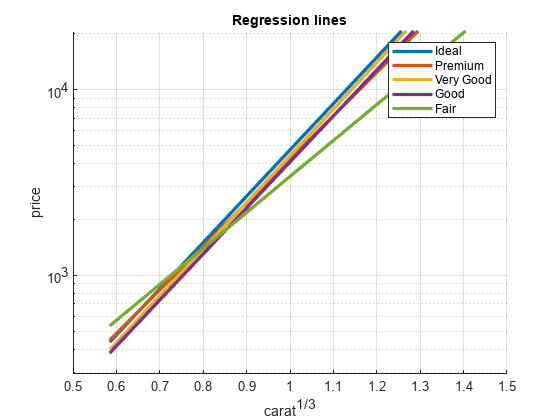



x1 = linspace(min(diamonds_filtered.carat.^(1/3)), max(diamonds_filtered.carat.^(1/3)), 1001);

figure
hold on
for ii = 1:size(cut_categories)
    idx = diamonds_filtered.cut==cut_categories(ii);

    [f, gof] = fit(diamonds_filtered.carat(idx).^(1/3), log(diamonds_filtered.price(idx)), 'poly1');
    semilogy(x1, exp(f.p1*x1 + f.p2), color=colors(ii,:), LineWidth=2.5)
end
hold off
set(gca,'YScale', 'log')
xlabel('carat^{1/3}')
ylabel('price')
grid on
ylim([min(diamonds_filtered.price)*0.9, max(diamonds_filtered.price)*1.1])
legend(cut_categories)
title(strcat('Regression lines'))
% saveas(gcf,strcat('02_Diamonds/carat_regression_cut_all.png') )